- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

% time to find
% hyp: time to find will depend on prior knowledge. 
timeArray = csvread('stats data/TimeToFind.csv');

timeArray(:,1)=timeArray(:,1)/2.27; % scaling to compensate for length and obstacles
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find (s)')
% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                        SumSq    DF    MeanSq      F       pValue       pValueGG      pValueHF     pValueLB 
                        _____    __    ______    _____    _________    __________    __________    _________

    (Intercept):cond    40292     3     13431    11.69    1.778e-06    2.1367e-05    1.0175e-05    0.0019441
    Error(cond)         96503    84    1148.8                                                               


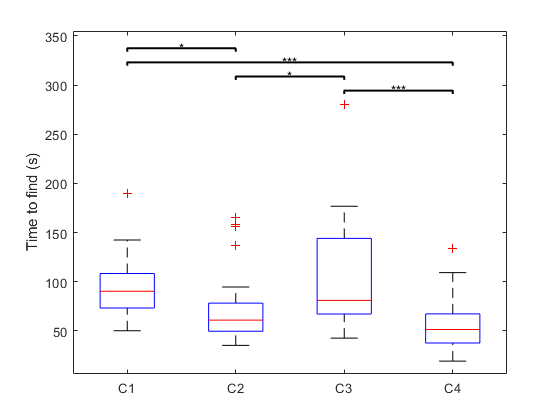

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper  
    ______    ______    __________    ______    __________    _______    ________

      1         2         22.748       7.257      0.024091      2.146       43.35
      1         3        -7.8269      10.481             1    -37.581      21.927
      1         4         39.322      6.7128    1.6112e-05     20.265      58.379
      2         1        -22.748       7.257      0.024091     -43.35      -2.146
      2         3        -30.575      10.728      0.048659     -61.03    -0.12031
      2         4         16.574      6.8058       0.12904    -2.7476      35.895
      3         1         7.8269      10.481             1    -21.927      37.581
 

if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_time,1);
end


%keyboard
% speed
% hyp: speed will depend on prior knowledge.
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average robot speed (m/s)')
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq     DF    MeanSq       F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    _______    ______    __________    __________    __________    _________

    (Intercept):cond    0.04668     3    0.01556    10.443    6.5521e-06    1.6876e-05    6.5521e-06    0.0031438
    Error(cond)         0.12516    84    0.00149                                                                 


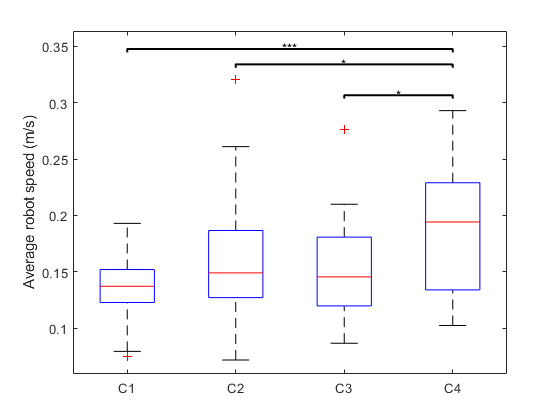

res_EKFSpd = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.022433     0.0083034      0.069491     -0.046006     0.0011395
      1         3       -0.015456     0.0091217       0.60764     -0.041352       0.01044
      1         4       -0.054994     0.0093071    1.4038e-05     -0.081416     -0.028572
      2         1        0.022433     0.0083034      0.069491    -0.0011395      0.046006
      2         3        0.006977       0.01145             1     -0.025529      0.039483
      2         4       -0.032561      0.010769      0.031803     -0.063134     -0.001987
      3         1

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFSpd,1);
end



% turn rate
% hyp: turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average robot turn rate (rad/s)')
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                        SumSq     DF    MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    _______    ______    ________    ________    ________    ________

    (Intercept):cond    1.5116     3    0.50386    3.2061    0.027241    0.039709    0.034934    0.084185
    Error(cond)         13.201    84    0.15716                                                          


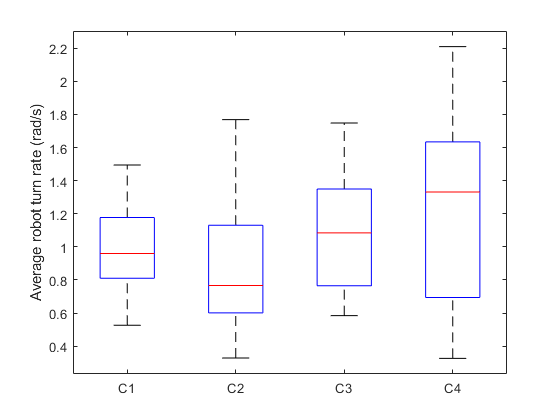

res_EKFOmega = 12×7 table
    cond_1    cond_2    Difference     StdErr     pValue       Lower       Upper  
    ______    ______    __________    ________    _______    _________    ________

      1         2        0.087183     0.092487          1     -0.17538     0.34975
      1         3        -0.11274      0.06589    0.58872      -0.2998    0.074312
      1         4        -0.21517      0.10394    0.28659     -0.51024    0.079894
      2         1       -0.087183     0.092487          1     -0.34975     0.17538
      2         3        -0.19993      0.10107    0.34706     -0.48687    0.087017
      2         4        -0.30236      0.12246    0.11949     -0.65001      0.0453
      3         1         0.11274      0.06589    0.58872    -0.074312 

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFOmega,1);
end


% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded speed (m/s)')
rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                         SumSq     DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.02796     3       0.00932    11.279    2.7221e-06    1.8052e-05    7.8956e-06    0.0022733
    Error(cond)         0.06941    84    0.00082631                                                                 


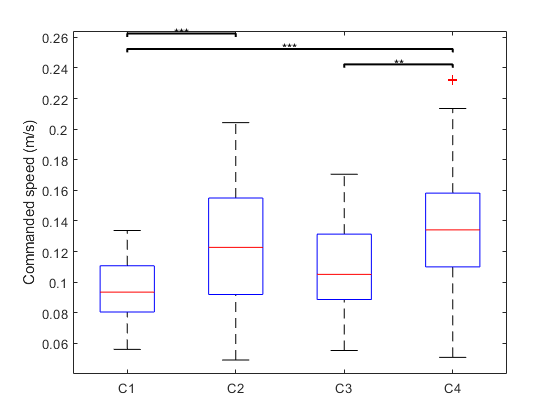

res_comSpeed = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.028955     0.0064117    0.00062418     -0.047157     -0.010753
      1         3       -0.013277     0.0054914       0.13423     -0.028867     0.0023125
      1         4       -0.041009     0.0083114    0.00019927     -0.064605     -0.017414
      2         1        0.028955     0.0064117    0.00062418      0.010753      0.047157
      2         3        0.015678      0.007368       0.25377    -0.0052397      0.036595
      2         4       -0.012054      0.009409             1     -0.038766      0.014658
      3        

if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end



% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded turn rate (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF      MeanSq        F        pValue       pValueGG      pValueHF      pValueLB 
                        ________    __    __________    _____    __________    __________    __________    __________

    (Intercept):cond    0.039969     3      0.013323    15.71    3.3924e-08    2.3749e-07    6.1468e-08    0.00046319
    Error(cond)         0.071235    84    0.00084803                                                                 


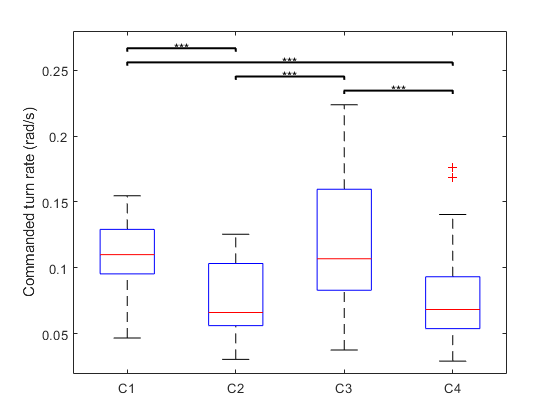

res_comTurnRate = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower        Upper  
    ______    ______    __________    _________    __________    _________    _________

      1         2         0.034673    0.0062224    3.4917e-05     0.017008     0.052338
      1         3       -0.0060331    0.0077197             1    -0.027949     0.015883
      1         4         0.033014    0.0060225    4.4667e-05     0.015916     0.050111
      2         1        -0.034673    0.0062224    3.4917e-05    -0.052338    -0.017008
      2         3        -0.040706    0.0088622    0.00050559    -0.065865    -0.015547
      2         4       -0.0016594     0.007815             1    -0.023846     0.020527
      3         1        0.0

if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end


% Total distance traveled
TotalDistArray = csvread('stats data/TotalDistanceTravel.csv');
TotalDistArray(:,1)=TotalDistArray(:,1)/2.27;
t_TotalDist = array2table(TotalDistArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalDist(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average total distance traveled (m)')
rm_TotalDist=fitrm(t_TotalDist,'C1-C4~1', 'WithinDesign', within);
stats_TotalDist = ranova(rm_TotalDist)

stats_TotalDist = 2×8 table
                        SumSq     DF    MeanSq      F         pValue      pValueGG     pValueHF     pValueLB
                        ______    __    ______    ______    __________    _________    _________    ________

    (Intercept):cond    663.41     3    221.14    6.5615    0.00048647    0.0025111    0.0018848    0.016095
    Error(cond)           2831    84    33.702                                                              


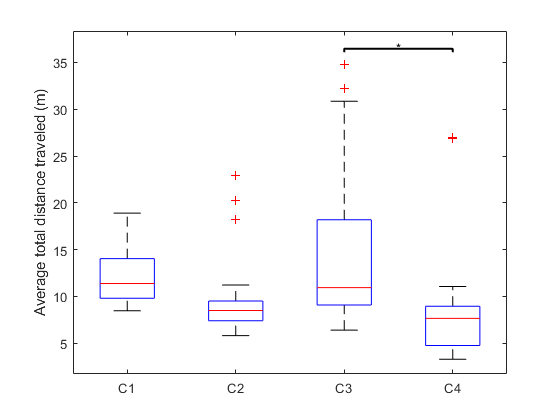

res_TotalDist = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper  
    ______    ______    __________    _______    ________    _________    ________

      1         2         2.5182      0.98214    0.096021     -0.27004      5.3064
      1         3        -2.4322       1.4986     0.69485      -6.6867      1.8223
      1         4         3.7919       1.3419     0.05161    -0.017571      7.6014
      2         1        -2.5182      0.98214    0.096021      -5.3064     0.27004
      2         3        -4.9504       1.7766    0.056755      -9.9941    0.093279
      2         4         1.2737       1.2525           1       -2.282      4.8295
      3         1         2.4322       1.4986     0.69485      -1.8223

if stats_TotalDist.pValue(1) < 0.05
    res_TotalDist=multcompare(rm_TotalDist, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalDist,1)
end


% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time in place (s)')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                        SumSq    DF    MeanSq      F         pValue       pValueGG      pValueHF     pValueLB 
                        _____    __    ______    ______    __________    __________    __________    _________

    (Intercept):cond    18476     3    6158.6    10.857    4.2312e-06    8.1168e-06    4.2312e-06    0.0026744
    Error(cond)         47648    84    567.24                                                                 


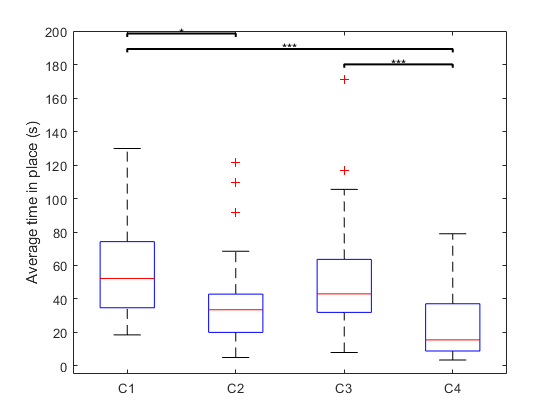

res_TotalTimeInPlace = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         15.758      5.0524      0.025062     1.4146     30.101
      1         3         1.1372       6.824             1    -18.236      20.51
      1         4         30.999      6.4261    0.00026929     12.756     49.243
      2         1        -15.758      5.0524      0.025062    -30.101    -1.4146
      2         3        -14.621      6.3543       0.17432     -32.66     3.4188
      2         4         15.241      5.9926       0.10072    -1.7712     32.254
      3         1        -1.1372       6.824             1     -20.51     18.23

if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end

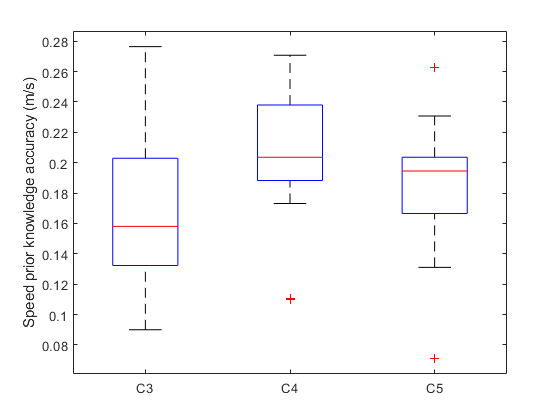



% speed between 3 and 4b
% knowledge of the target not present in location 1 implies it's presence in location 2, 
% thus leading to an increase in speed which resembles when target location is known in 4a
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
EKFSpdData = EKFSpdData(EKFSpdData(:,5)~=0,[3,4, 5]);
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2', 'C3'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:3)), 'labels', {'C3','C4', 'C5'});
ylabel('Speed prior knowledge accuracy (m/s)')

within3=array2table([1 2 3]', 'variablenames', {'cond'});
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C3~1', 'WithinDesign', within3);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                          SumSq      DF     MeanSq        F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    _________    ______    _______    ________    ________    ________

    (Intercept):cond    0.0089582     2    0.0044791    2.4779    0.10352    0.10883     0.10352     0.13947 
    Error(cond)          0.046998    26    0.0018076                                                         


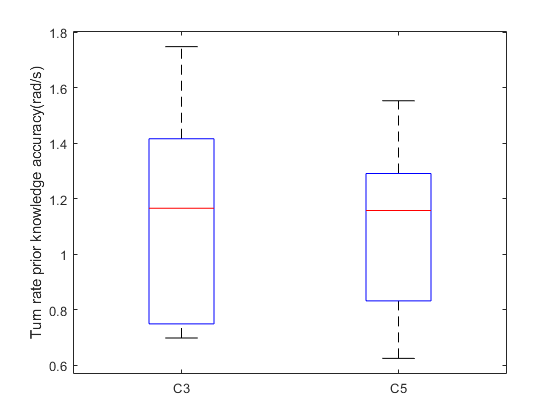

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
end

EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
EKFOmegaArray = EKFOmegaArray((EKFOmegaArray(:,5) ~= 0), [3,5]);
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:2)), 'labels', {'C3','C5'});
ylabel('Turn rate prior knowledge accuracy(rad/s)')

within2=array2table([1 2]', 'variablenames', {'cond'});
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C2~1', 'WithinDesign', within2);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                          SumSq      DF     MeanSq         F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    _________    _______    _______    ________    ________    ________

    (Intercept):cond    0.0083763     1    0.0083763    0.10443    0.75172    0.75172     0.75172     0.75172 
    Error(cond)            1.0428    13     0.080213                                                          


if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
end


% stopping percentage (bearings)
% hyp: stopping percentage will depend on prior knowledge. 
% higher stopping percentage when map is not known
% Total time in place traveled
TotalTimeStoppingArray = csvread('stats data/TotalTimeStopping.csv');
t_TotalTimeStoppingArray = array2table(TotalTimeStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotaltimeStopping_bp = boxplot(table2array(t_TotalTimeStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time in place (s)')
rm_TotalTimeStoppingArray=fitrm(t_TotalTimeStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeStoppingArray = ranova(rm_TotalTimeStoppingArray)

stats_TotalTimeStoppingArray = 2×8 table
                        SumSq    DF    MeanSq      F         pValue       pValueGG      pValueHF      pValueLB 
                        _____    __    ______    ______    __________    __________    __________    __________

    (Intercept):cond    54069     3     18023    56.079    5.3232e-20    5.5829e-16    2.7415e-17    3.7155e-08
    Error(cond)         26996    84    321.38                                                                  


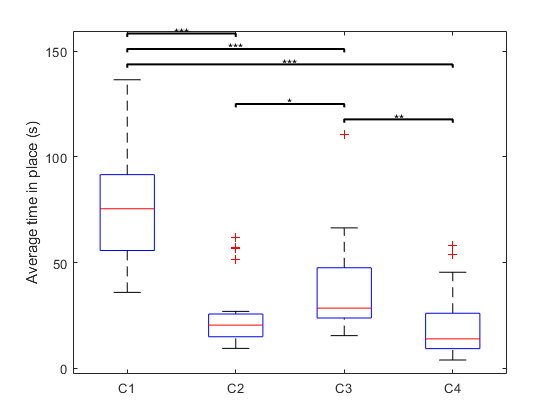

res_TotalTimeStoppingArray = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         50.655      4.6799    9.7769e-11     37.369     63.941
      1         3         37.448      5.3201    7.0511e-07     22.345     52.552
      1         4         54.759      6.0004    4.1797e-09     37.724     71.793
      2         1        -50.655      4.6799    9.7769e-11    -63.941    -37.369
      2         3        -13.207      4.0539      0.017641    -24.716    -1.6982
      2         4         4.1034      3.4223             1    -5.6122     13.819
      3         1        -37.448      5.3201    7.0511e-07    -52.552    

if stats_TotalTimeStoppingArray.pValue(1) < 0.05
    res_TotalTimeStoppingArray=multcompare(rm_TotalTimeStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeStoppingArray,1)
end


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average percent in place (s)')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                         SumSq     DF     MeanSq       F        pValue      pValueGG     pValueHF     pValueLB
                        _______    __    ________    ______    _________    _________    _________    ________

    (Intercept):cond    0.22735     3    0.075784    7.2713    0.0002149    0.0055908    0.0050929    0.011724
    Error(cond)         0.87547    84    0.010422                                                             


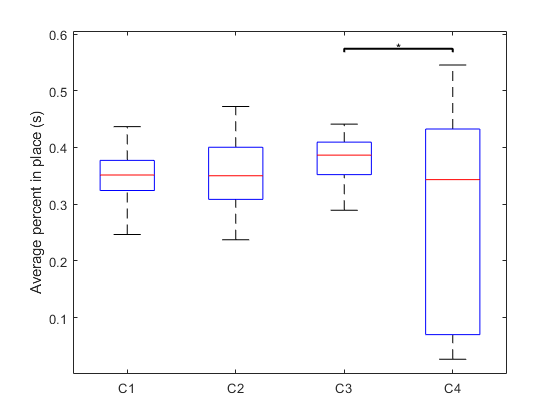

res_TotalPercentStoppingArray = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper   
    ______    ______    __________    _________    ________    ___________    __________

      1         2        -0.00353      0.015659           1      -0.047985      0.040925
      1         3       -0.025872     0.0093643    0.060054      -0.052457    0.00071211
      1         4        0.089839      0.037599     0.14311      -0.016901       0.19658
      2         1         0.00353      0.015659           1      -0.040925      0.047985
      2         3       -0.022342      0.013852     0.70782      -0.061667      0.016982
      2         4        0.093369      0.034004    0.062556     -0.0031657        0.1899
      

if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end




% NASA TLX
% all stats
% -- Questions that were on the NASA TLX with the corresponding value bar range
% -- Q1) Mental demand: Low - High
% -- Q2) Physical demand: Low - High
% -- Q3) Temporal demand: Low - High
% -- Q4) Performance: Perfect - Failure
% -- Q5) Effort: Low - High
% -- Q6) Frustration: Low - High

NASATLXArray = csvread('stats data/NASATLXResults.csv');
t_NASATLX = array2table(NASATLXArray,...
    'VariableNames',{'Q1','Q2','Q3','Q4','Q5','Q6'});
NASATLX_bp = boxplot(table2array(t_NASATLX), 'labels', {'Q1','Q2','Q3','Q4','Q5','Q6'});
ylabel('Question response')
within2=array2table([1 2 3 4 5 6]', 'variablenames', {'cond'});
rm_NASATLX=fitrm(t_NASATLX,'Q1-Q6~1', 'WithinDesign', within2);
stats_NASATLX = ranova(rm_NASATLX)

stats_NASATLX = 2×8 table
                        SumSq    DF     MeanSq      F         pValue       pValueGG      pValueHF     pValueLB 
                        _____    ___    ______    ______    __________    __________    __________    _________

    (Intercept):cond     8590      5      1718    13.803    5.8668e-11    2.1494e-08    1.9845e-09    0.0008966
    Error(cond)         17425    140    124.46                                                                 


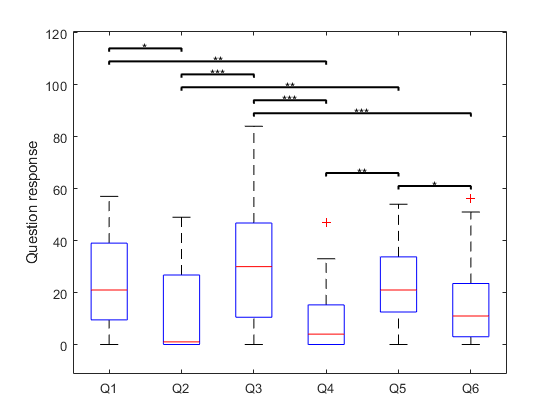

res_NASATLX = 30×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper  
    ______    ______    __________    ______    __________    ________    ________

      1         2         10.414      2.9472      0.021675     0.95794       19.87
      1         3        -6.7586      3.4704       0.92346     -17.893      4.3758
      1         4             14      3.1929       0.00223      3.7559      24.244
      1         5        0.27586      2.0275             1     -6.2291      6.7808
      1         6         7.1034       2.492       0.12155    -0.89202      15.099
      2         1        -10.414      2.9472      0.021675      -19.87    -0.95794
      2         3        -17.172      3.0594    7.8147e-05     -26.988  

if stats_NASATLX.pValue(1) < 0.05
    res_NASATLX=multcompare(rm_NASATLX, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLX,1)
end


% -- commanded acceleration
ComAccelArray = csvread('stats data/CommandedAccel.csv');
t_ComAccelArray = array2table(ComAccelArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
ComAccelArray_bp = boxplot(table2array(t_ComAccelArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average percent in place (s)')
rm_ComAccelArray=fitrm(t_ComAccelArray,'C1-C4~1', 'WithinDesign', within);
stats_ComAccelArray = ranova(rm_ComAccelArray)

stats_ComAccelArray = 2×8 table
                          SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond     0.001777     3    0.00059234    13.017    4.6291e-07    0.00079203    0.00075578    0.0011895
    Error(cond)         0.0038225    84    4.5507e-05                                                                 


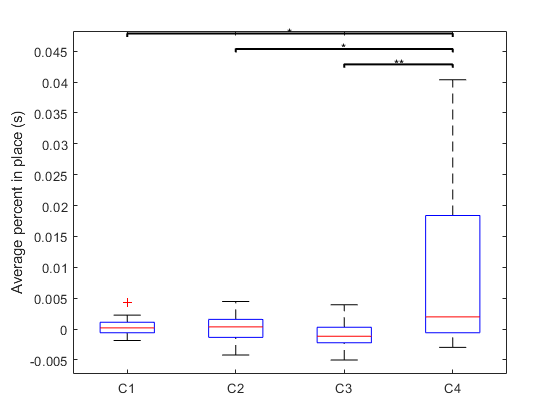

res_ComAccelArray = 12×7 table
    cond_1    cond_2    Difference       StdErr       pValue         Lower         Upper   
    ______    ______    ___________    __________    _________    ___________    __________

      1         2        5.1992e-05    0.00042303            1      -0.001149     0.0012529
      1         3         0.0012185    0.00045367     0.072152    -6.9451e-05     0.0025064
      1         4        -0.0085451     0.0024674     0.010408       -0.01555    -0.0015403
      2         1       -5.1992e-05    0.00042303            1     -0.0012529      0.001149
      2         3         0.0011665    0.00055776      0.27412    -0.00041695     0.0027499
      2         4        -0.0085971     0.0025042     0.011252      -0.015706    -0.00

if stats_ComAccelArray.pValue(1) < 0.05
    res_ComAccelArray=multcompare(rm_ComAccelArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_ComAccelArray,1)
end


% post trial


% we place target in a different location in 4b to see the change in behavior
% when the participant realizes that their prior knowledge is inaccurate
% we compared the actions between condition 3, when they did not have any knowledge
% of target location and condition 4b, when they again don't have knowledge about target location
% but thought they did
% 3 and 4b


% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% % t_TotalTimeInPlace
% % t_TotalTimeStoppingArray
% % t_TotalPercentStoppingArray
% % t_NASATLX
% % t_ComAccelArray
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% rm_TotalTimeInPlace
% rm_TotalTimeStoppingArray
% rm_TotalPercentStoppingArray
% rm_NASATLX
% rm_ComAccelArray
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 